# `DEMO_02b:`   4-bar linkage analysis - `dynamics (`*alternate approach*`)`

Let's derive the Equations of Motion (EoM) of a 4bar linkage - see Figure_01 below.  In this approach we'll still use the Lagrangian dynamics technique, but we'll formulate the problem in a slightly different way.  As discussed in the previous kinematic analysis, the 4bar mechanism is a single degree of freedom system, even though there are clearly 3 angles describing the mechanism's pose -  $\theta ,\;\alpha ,\;\phi$.  These 3 angles are related by the kinematic positional constraints defined by:

- 
$$X\;\textrm{direction}\Longrightarrow \;\;\;\;\;\;\;\;f\left(\theta ,\;\alpha ,\;\phi \right)=\;\;0\;\;=\;{\;\;\;L}_1 \;\ldotp \cos \left(\theta \right)\;\;+\;L_2 \ldotp \cos \left(\alpha \right)\;-\;L_3 \ldotp \cos \left(\phi \right)-\;L_4 \;\;\;$$


- 
$$Y\;\textrm{direction}\Longrightarrow \;\;\;\;\;\;\;\;\;g\left(\theta ,\;\alpha ,\;\phi \right)=\;\;0\;\;=\;\;\;\;\;L_1 \ldotp \sin \left(\theta \right)\;\;\;+\;\;L_2 \ldotp \sin \left(\alpha \right)\;-\;\;\;\;L_3 \ldotp \sin \left(\phi \right)\;$$


If we want to use a Lagrangian approach to derive the machine's equations of motion, we can still use the 3 generalised co-ordinates of $\theta ,\;\alpha ,\;\phi$, but we need to use a version of the Lagrangian equation which incorporates the kinematic constraints relating these angles.  This modified version of the Lagrangian equation has the form:

- $\frac{d}{\textrm{dt}}\frac{\partial L}{\partial \dot{q_k } }\;\;\;-\;\;\frac{\partial L}{\partial q_k }\;\;\;=\;\;\;Q_k \;\;+\;\;\;\frac{\partial }{\partial q_k }\left(\lambda_1 \ldotp f\;\;\;+\;\;\;\;\lambda_2 \ldotp g\;\right)$         for    $q_k =\;\theta ,\;\alpha ,\;\phi$

Where $\lambda_1$ and $\lambda_2$ are our Lagrangian multipliers. 

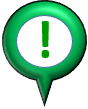** NOTE:**

- 
$$\delta f\;\;=\;\;\frac{\partial f}{\partial \theta }\ldotp \delta \theta \;\;+\;\;\frac{\partial f}{\partial \alpha }\ldotp \delta \alpha \;\;+\;\;\frac{\partial f}{\partial \phi }\ldotp \delta \phi \;\;\;=\;\sum_{k=1}^3 \frac{\partial f}{\partial q_k }\ldotp \delta q_k$$


- 
$$\delta g\;\;=\;\;\frac{\partial g}{\partial \theta }\ldotp \delta \theta \;\;\;+\;\;\frac{\partial g}{\partial \alpha }\ldotp \delta \alpha \;\;+\;\;\frac{\partial g}{\partial \phi }\ldotp \delta \phi \;\;\;=\;\sum_{k=1}^3 \frac{\partial g}{\partial q_k }\ldotp \delta q_k$$


**Figure 01:  the 4bar linkage**

  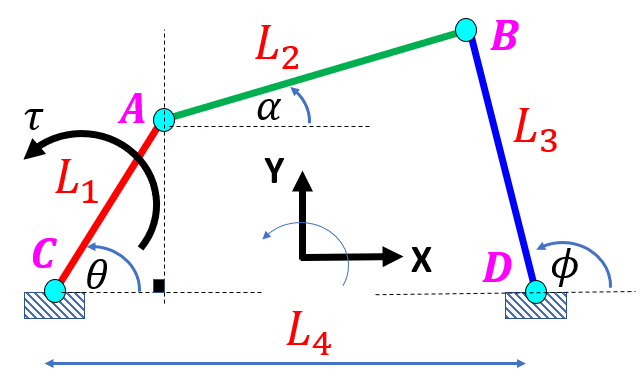

`Bradley Horton : 11-Nov-2019, bhorton@mathworks.com`

### Define the main collection of symbols

syms L_1  L_2  L_3  L_4  real  % bar lengths
syms I_1  I_2  I_3       real  % bar inertias about CoM
syms m_1  m_2  m_3  g    real  % bar masses

syms tau_1              real   % applied torque to bar 1
syms lambda_1  lambda_2 real   % lagrange multipliers for the kinematic constraints

syms THETA(t)  ALPHA(t)  PHI(t)

syms theta  theta_dot  theta_ddot real
syms alpha  alpha_dot  alpha_ddot real
syms   phi    phi_dot    phi_ddot real

#### Define the main and HOLDER symbol lists

% MAIN_sym_list = [      THETA(t),           ALPHA(t),           PHI(t)      , ...
%                   diff(THETA(t),t,1), diff(ALPHA(t),t,1), diff(PHI(t),t,1) , ...
%                   diff(THETA(t),t,2), diff(ALPHA(t),t,2), diff(PHI(t),t,2) 
%                 ];
%             
% HOLD_sym_list = [   theta,         alpha,         phi        , ...   
%                     theta_dot,     alpha_dot,     phi_dot    , ...
%                     theta_ddot,    alpha_ddot,    phi_ddot
%                 ];

MAIN_sym_list = [  diff(THETA(t),t,2), diff(ALPHA(t),t,2), diff(PHI(t),t,2) , ...    
                   diff(THETA(t),t,1), diff(ALPHA(t),t,1), diff(PHI(t),t,1) , ...  
                             THETA(t),           ALPHA(t),           PHI(t) , ...                  
                ];
            
HOLD_sym_list = [   theta_ddot,    alpha_ddot,    phi_ddot,  ...
                    theta_dot,     alpha_dot,     phi_dot,   ...    
                        theta,         alpha,         phi,   ...                      
                ];

#### Define the system KINETIC and POTENTIAL Energies

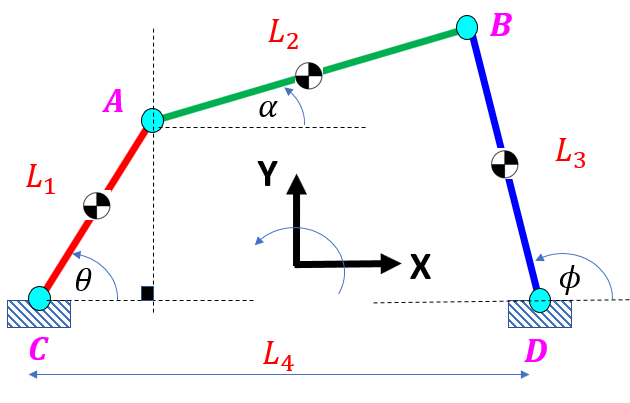

The angular velocities for the 3 bars are

- 
$${\left\lbrack \begin{array}{ccc}
\omega_1  & \omega_2  & \omega_3 
\end{array}\right\rbrack }^T \;\;=\;\;{\left\lbrack \begin{array}{ccc}
\dot{\theta}  & \dot{\alpha}  & \dot{\phi} 
\end{array}\right\rbrack }^T$$


The ${\left\lbrack \begin{array}{cc}
x & y
\end{array}\right\rbrack }^T$ centre of mass  POSITION vectors for our 3 bars are:

***NOTE: we're assuming that point C is the origin***

- 
$${\textrm{POS}}_{\textrm{G1}} ={\left\lbrack \begin{array}{cc}
\left(\frac{L_1 }{2}\ldotp \cos \left(\theta \right)\right)\;,\; & \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\frac{L_1 }{2}\ldotp \sin \left(\theta \right)\right)
\end{array}\right\rbrack }^T \;\;\;\;\;$$
  

- 
$${\textrm{POS}}_{\textrm{G2}} ={\left\lbrack \begin{array}{cc}
\left(L_1 \ldotp \cos \left(\theta \right)\;+\;\frac{L_2 }{2}\ldotp \cos \left(\alpha \right)\right)\;,\;\; & \left(L_1 \ldotp \sin \left(\theta \right)\;+\;\frac{L_2 }{2}\ldotp \sin \left(\alpha \right)\right)
\end{array}\right\rbrack }^T$$


- 
$${\textrm{POS}}_{\textrm{G3}} ={\left\lbrack \begin{array}{cc}
\left(L_4 \;\;+\;\;\frac{L_3 }{2}\ldotp \cos \left(\phi \right)\right)\;,\; & \;\;\;\;\;\;\;\;\;\;\;\;\;\left(\frac{L_3 }{2}\ldotp \sin \left(\phi \right)\;\;\;\;\;\;\right)
\end{array}\right\rbrack }^T \;$$
                     

So we can compute the translational velocities of these centre of masses:

- 
$$v\;=\;\frac{d}{\textrm{dt}}\left(\textrm{POS}\right)$$


 v1_col = diff(  [ (      0.5*L_1*cos(THETA(t)) );   (0.5*L_1*sin(THETA(t)) )  ], t    ); 
 v3_col = diff(  [ (L_4 + 0.5*L_3*cos(  PHI(t)) );   (0.5*L_3*sin  (PHI(t)) )  ], t    ); 
 v2_col = diff(  [ (L_1*cos(THETA(t)) + 0.5*L_2*cos(ALPHA(t))); ...
                   (L_1*sin(THETA(t)) + 0.5*L_2*sin(ALPHA(t)))                 ], t    ); 

If we attach BODY frames to the **centre of masses** of each bar, the kinetic energy for the $i^{\textrm{th}}$ body can be stated as:

- 
$${\textrm{KE}}_i \;\;\;=\;\;\;\;\;\frac{1}{2}v_{{\textrm{cm}}_i }^T {\ldotp \;m}_i {\;\ldotp v}_{{\textrm{cm}}_i } \;\;\;+\;\;\;\;\;\frac{1}{2}\ldotp \omega_{B_i }^T \ldotp \left\lbrack I_{{\textrm{cm}}_i } \right\rbrack \ldotp \omega_{B_i }$$


The total system kinetic energy is then just the sum of the "*N*" individual kinetic energies. 

- 
$${\textrm{KE}}_{\textrm{system}} \;\;\;=\;\;\;\;\sum_{i=1}^N {\textrm{KE}}_i$$
       

 KE = 0.5*(  m_1*v1_col.'*v1_col      +  m_2*v2_col.'*v2_col      +   m_3*v3_col.'*v3_col    )  + ...
      0.5*(  I_1*diff(THETA(t),t)^2   +  I_2*diff(ALPHA(t),t)^2   +   I_3*diff(PHI(t),t)^2   );
  
 KE = simplify(KE); 

#### Define the POTENTIAL energy

Similarly we can define our "system" Potential Energy as the sum of the "*N*" individual potential energies

-    ${\textrm{PE}}_{\textrm{system}} =\;\sum_{i=1}^N {\textrm{PE}}_i$       where      ${\textrm{PE}}_i \;=\;\int_{y_{i\_\textrm{CG}} }^0 \;-m_i \;\ldotp g\ldotp \textrm{dy}\;\;=\;\;\;m_i \ldotp g\ldotp y_{i\_\textrm{CG}}$ 

  PE = g*(  m_1*sin(THETA(t))*L_1/2     + ...
            m_3*sin(PHI(t)  )*L_3/2     + ...
            m_2*(L_1*sin(THETA(t)) + sin(ALPHA(t))*L_2/2)  );

#### Define the LAGRANGIAN 

Our system Lagrangian can now be defined:

THE_L = KE - PE;

So what does this **actually** look like ? - display using the HOLDER symbols:

subs(THE_L, MAIN_sym_list, HOLD_sym_list)

$$ans = \frac{I_{2}\,{\dot{\alpha }}^{2}}{2}-g\,\left(m_{2}\,\left(\frac{L_{2}\,\sin\left(\alpha \right)}{2}+L_{1}\,\sin\left(\theta \right)\right)+\frac{L_{1}\,m_{1}\,\sin\left(\theta \right)}{2}+\frac{L_{3}\,m_{3}\,\sin\left(\varphi \right)}{2}\right)+\frac{I_{3}\,{\dot{\varphi }}^{2}}{2}+\frac{I_{1}\,{\dot{\theta }}^{2}}{2}+\frac{{L_{2}}^{2}\,{\dot{\alpha }}^{2}\,m_{2}}{8}+\frac{{L_{3}}^{2}\,m_{3}\,{\dot{\varphi }}^{2}}{8}+\frac{{L_{1}}^{2}\,m_{1}\,{\dot{\theta }}^{2}}{8}+\frac{{L_{1}}^{2}\,m_{2}\,{\dot{\theta }}^{2}}{2}+\frac{L_{1}\,L_{2}\,\dot{\alpha }\,m_{2}\,\dot{\theta }\,\cos\left(\alpha -\theta \right)}{2}$$

#### Apply Lagranges equation

- $\frac{d}{\textrm{dt}}\frac{\partial L}{\partial \dot{q_k } }\;\;\;-\;\;\frac{\partial L}{\partial q_k }\;\;\;=\;\;\;Q_k$           for    $q_k =\;\theta ,\;\alpha ,\;\phi$

See the local subfunction LOC_do_lagrange at the bottom of this script for the implementation

EQ1_LHS =   LOC_do_lagrange( THE_L, [theta, theta_dot], MAIN_sym_list, HOLD_sym_list );
EQ2_LHS =   LOC_do_lagrange( THE_L, [alpha, alpha_dot], MAIN_sym_list, HOLD_sym_list );
EQ3_LHS =   LOC_do_lagrange (THE_L, [phi,     phi_dot], MAIN_sym_list, HOLD_sym_list );

*NOTE:  the only non conservative torque is the External torque *$\tau_1$* applied to BAR #1*

EQ1_RHS =   tau_1;
EQ2_RHS =   sym(0);
EQ3_RHS =   sym(0);

What do these equations look like ?  As an example, let's look at the LHS of our first equation:

EQ1_LHS

$$EQ1\_LHS = g\,\left(\frac{L_{1}\,m_{1}\,\cos\left(\theta \right)}{2}+L_{1}\,m_{2}\,\cos\left(\theta \right)\right)+I_{1}\,\ddot{\theta }+\frac{{L_{1}}^{2}\,m_{1}\,\ddot{\theta }}{4}+{L_{1}}^{2}\,m_{2}\,\ddot{\theta }+\frac{L_{1}\,L_{2}\,\ddot{\alpha }\,m_{2}\,\cos\left(\alpha -\theta \right)}{2}-\frac{L_{1}\,L_{2}\,\dot{\alpha }\,m_{2}\,\dot{\theta }\,\sin\left(\alpha -\theta \right)}{2}-\frac{L_{1}\,L_{2}\,\dot{\alpha }\,m_{2}\,\sin\left(\alpha -\theta \right)\,\left(\dot{\alpha }-\dot{\theta }\right)}{2}$$

 *Note:   ****We haven't finished yet***

- *We still have to incorporate our constraints into these equations*

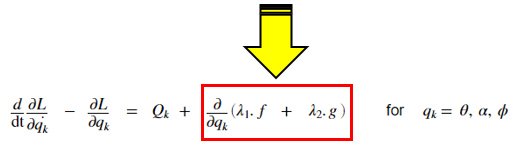

### Define the position CONSTRAINT equations:

The angles $\left\lbrack \theta ,\;\alpha ,\;\phi \right\rbrack$ are related by the constraint equations:

- 
$$X\;\textrm{direction}\Longrightarrow \;\;\;\;\;\;\;\;f\left(\theta ,\;\alpha ,\;\phi \right)=\;\;\;0\;\;=\;{\;\;\;L}_1 \;\ldotp \cos \left(\theta \right)\;\;+\;L_2 \ldotp \cos \left(\alpha \right)\;-\;L_3 \ldotp \cos \left(\phi \right)-\;L_4 \;\;\;$$


- 
$$Y\;\textrm{direction}\Longrightarrow \;\;\;\;\;\;\;\;\;g\left(\theta ,\;\alpha ,\;\phi \right)=\;\;\;0\;\;=\;\;\;\;\;L_1 \ldotp \sin \left(\theta \right)\;\;\;+\;\;L_2 \ldotp \sin \left(\alpha \right)\;-\;\;\;\;L_3 \ldotp \sin \left(\phi \right)\;$$


CONS_EQ_POS_X =   0 == L_1*cos(THETA(t)) + L_2*cos(ALPHA(t)) - L_3*cos(PHI(t)) - L_4;
CONS_EQ_POS_Y =   0 == L_1*sin(THETA(t)) + L_2*sin(ALPHA(t)) - L_3*sin(PHI(t));

And use the HOLD symbols in these constraint equations:

CONS_EQ_POS_X_HOLD = subs(CONS_EQ_POS_X, MAIN_sym_list, HOLD_sym_list);
CONS_EQ_POS_Y_HOLD = subs(CONS_EQ_POS_Y, MAIN_sym_list, HOLD_sym_list);

Multiply our positional contraints by Lagrange multipliers AND add together the 2 positional contraints:

- 
$$\;0\;\;\;=\;\;\;f\left(\theta ,\;\alpha ,\;\phi \right)\;\;$$


- 
$$\;0\;\;\;=\;\;\;g\left(\theta ,\;\alpha ,\;\phi \right)$$


- 
$$\;0\;\;\;=\;\;\;\lambda_1 \ldotp f\left(\theta ,\;\alpha ,\;\phi \right)\;\;\;+\;\;\;\;\lambda_2 \ldotp g\left(\theta ,\;\alpha ,\;\phi \right)$$


CONS_EQ_ZERO_POS_LAMBDA = lambda_1*CONS_EQ_POS_X_HOLD  +  lambda_2*CONS_EQ_POS_Y_HOLD

$$CONS\_EQ\_ZERO\_POS\_LAMBDA = 0=\lambda_{2}\,\left(L_{2}\,\sin\left(\alpha \right)-L_{3}\,\sin\left(\varphi \right)+L_{1}\,\sin\left(\theta \right)\right)-\lambda_{1}\,\left(L_{4}-L_{2}\,\cos\left(\alpha \right)+L_{3}\,\cos\left(\varphi \right)-L_{1}\,\cos\left(\theta \right)\right)$$

 Note:   

- *So now we have this bit*

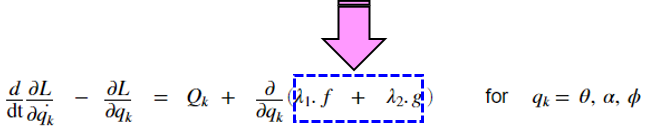

#### Define the acceleration CONSTRAINT equations:

  *WHY are we doing this bit ?   *

- *At the moment we have 3 ODE equations with 5 UNKNOWNS: *$\ddot{\theta} \;,\ddot{\alpha} \;,\ddot{\phi} ,\lambda_1 \;\;,\lambda_2$

- *So ? - We need 2 more equations to help us solve for the unknowns*

I'd like to differentiate(twice) the positional constraints to get acceleration constraints:

***WHY ? - because we'll use these as our "extra" equations to help us solve for the "unknowns"***

- 
$$X\;\textrm{direction}\Longrightarrow \;\;\;\;\;\;\;\frac{d^2 }{{\textrm{dt}}^2 }\left(f\left(\theta ,\;\alpha ,\;\phi \right)\;\right)\;=\;\;\;0\;\;=\;\;\frac{d^2 }{{\textrm{dt}}^2 }\left({\;\;\;L}_1 \;\ldotp \cos \left(\theta \right)\;\;+\;L_2 \ldotp \cos \left(\alpha \right)\;-\;L_3 \ldotp \cos \left(\phi \right)-\;L_4 \;\;\right)\;\;\;\;$$


- 
$$Y\;\textrm{direction}\Longrightarrow \;\;\;\;\;\;\frac{d^2 }{{\textrm{dt}}^2 }\left(\;g\left(\theta ,\;\alpha ,\;\phi \right)\;\right)\;\;=\;\;\;0\;\;=\;\;\frac{d^2 }{{\textrm{dt}}^2 }\left({\;\;L}_1 \ldotp \sin \left(\theta \right)\;\;\;+\;\;L_2 \ldotp \sin \left(\alpha \right)\;-\;\;\;\;L_3 \ldotp \sin \left(\phi \right)\;\;\;\right)\;\;\;\;\;$$


CONS_EQ_ACC_X      = diff(CONS_EQ_POS_X, t, 2);
CONS_EQ_ACC_Y      = diff(CONS_EQ_POS_Y, t, 2);
CONS_EQ_ACC_X_HOLD = subs(CONS_EQ_ACC_X, MAIN_sym_list, HOLD_sym_list);
CONS_EQ_ACC_Y_HOLD = subs(CONS_EQ_ACC_Y, MAIN_sym_list, HOLD_sym_list);

What do these acceleration constraint equations look like ?

[ CONS_EQ_ACC_X_HOLD;
  CONS_EQ_ACC_Y_HOLD  ]

$$ans = \left(\begin{array}{c} 0=-L_{2}\,\cos\left(\alpha \right)\,{\dot{\alpha }}^{2}+L_{3}\,\cos\left(\varphi \right)\,{\dot{\varphi }}^{2}-L_{1}\,\cos\left(\theta \right)\,{\dot{\theta }}^{2}+L_{3}\,\ddot{\varphi }\,\sin\left(\varphi \right)-L_{1}\,\ddot{\theta }\,\sin\left(\theta \right)-L_{2}\,\ddot{\alpha }\,\sin\left(\alpha \right)\\ 0=-L_{2}\,\sin\left(\alpha \right)\,{\dot{\alpha }}^{2}+L_{3}\,\sin\left(\varphi \right)\,{\dot{\varphi }}^{2}-L_{1}\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+L_{2}\,\ddot{\alpha }\,\cos\left(\alpha \right)-L_{3}\,\ddot{\varphi }\,\cos\left(\varphi \right)+L_{1}\,\ddot{\theta }\,\cos\left(\theta \right) \end{array}\right)$$

### Incorporate the POSITIONAL constraints into the Lagrange equations:

We take the variation of the position constraint equations and add these to the RHS of our Lagrangian equations, ie:

- 
$$\frac{d}{\textrm{dt}}\frac{\partial L}{\partial \dot{q_k } }\;\;\;-\;\;\frac{\partial L}{\partial q_k }\;\;\;=\;\;\;Q_k \;\;+\;\;\;\frac{\partial }{\partial q_k }\left(\lambda_1 \ldotp f\;\;\;+\;\;\;\;\lambda_2 \ldotp g\;\right)$$


Implement for $q_k =\theta$

EQ1_RHS =  EQ1_RHS  +  diff( rhs(CONS_EQ_ZERO_POS_LAMBDA), theta )

$$EQ1\_RHS = \tau_{1}+L_{1}\,\lambda_{2}\,\cos\left(\theta \right)-L_{1}\,\lambda_{1}\,\sin\left(\theta \right)$$

Implement for $q_k =\alpha$

EQ2_RHS =  EQ2_RHS  +  diff( rhs(CONS_EQ_ZERO_POS_LAMBDA), alpha )

$$EQ2\_RHS = L_{2}\,\lambda_{2}\,\cos\left(\alpha \right)-L_{2}\,\lambda_{1}\,\sin\left(\alpha \right)$$

Implement for $q_k =\phi$

EQ3_RHS =  EQ3_RHS  +  diff( rhs(CONS_EQ_ZERO_POS_LAMBDA), phi )

$$EQ3\_RHS = L_{3}\,\lambda_{1}\,\sin\left(\varphi \right)-L_{3}\,\lambda_{2}\,\cos\left(\varphi \right)$$

### Now define our final 5 equations:

The first 3 equations are our Lagrangian equations and the last 2 equations are our acceleration constraint equations

EQ_SYS = [  (EQ1_LHS == EQ1_RHS);
            (EQ2_LHS == EQ2_RHS);
            (EQ3_LHS == EQ3_RHS);
            CONS_EQ_ACC_X_HOLD;
            CONS_EQ_ACC_Y_HOLD;    ];

What do they look like ?

EQ_SYS

When you look at these system equations, you can see the following:

- The angular acceleration terms $\ddot{\theta} ,\ddot{\alpha} ,\ddot{\phi}$ appear as LINEAR terms, ie:     $\textrm{someCoefficient}\ldotp \ddot{\theta}$

- The Lagrange multiplier terms $\lambda_1 ,\lambda_2$ appear as LINEAR terms,     ie:     $\textrm{someOtherCoefficient}\ldotp \lambda_1$

- We have 5 equations and 5 unknowns, ie:  $\left\lbrack \begin{array}{ccccc}
\ddot{\theta}  & \ddot{\alpha}  & \ddot{\phi}  & \lambda_1  & \lambda_2 
\end{array}\right\rbrack$

So what we can do is treat our system of ODEs as just a simple set of simultaneous equations.  We can rearrange our system equations into the familiar  form $A\ldotp x=b$, ie:

- 
$$A\;\ldotp x\;\;=\;\;b$$


- 
$${\left\lbrack \begin{array}{c}
\;\;\;\;A\left(\theta ,\alpha ,\phi ,\dot{\theta} ,\dot{\alpha} ,\dot{\phi} \right)\;\;\;\;
\end{array}\right\rbrack }_{5\textrm{x5}} \;\;\;\ldotp \;\;\left\lbrack \begin{array}{c}
\ddot{\theta} \\
\ddot{\alpha} \\
\ddot{\phi} \\
\lambda_1 \\
\lambda_2 
\end{array}\right\rbrack ={\left\lbrack \begin{array}{c}
b\left(\theta ,\alpha ,\phi ,\dot{\theta} ,\dot{\alpha} ,\dot{\phi} \right)
\end{array}\right\rbrack }_{5\textrm{x1}}$$


#### Convert these system equations into the matrix form  *A.x = b* :

Let, 

- 
$$x={\left\lbrack \begin{array}{ccccc}
\ddot{\theta}  & \ddot{\alpha}  & \ddot{\phi}  & \lambda_1  & \lambda_2 
\end{array}\right\rbrack }^T$$
 

now rearrange our system equations into the form:

- 
$$A\;\ldotp x\;=\;b$$


[A,b] = equationsToMatrix(EQ_SYS,[theta_ddot, alpha_ddot, phi_ddot, lambda_1, lambda_2])

$$A = \left(\begin{array}{ccccc} I_{1}+\frac{{L_{1}}^{2}\,m_{1}}{4}+{L_{1}}^{2}\,m_{2} & \frac{L_{1}\,L_{2}\,m_{2}\,\cos\left(\alpha -\theta \right)}{2} & 0 & L_{1}\,\sin\left(\theta \right) & -L_{1}\,\cos\left(\theta \right)\\ \frac{L_{1}\,L_{2}\,m_{2}\,\cos\left(\alpha -\theta \right)}{2} & \frac{m_{2}\,{L_{2}}^{2}}{4}+I_{2} & 0 & L_{2}\,\sin\left(\alpha \right) & -L_{2}\,\cos\left(\alpha \right)\\ 0 & 0 & \frac{m_{3}\,{L_{3}}^{2}}{4}+I_{3} & -L_{3}\,\sin\left(\varphi \right) & L_{3}\,\cos\left(\varphi \right)\\ L_{1}\,\sin\left(\theta \right) & L_{2}\,\sin\left(\alpha \right) & -L_{3}\,\sin\left(\varphi \right) & 0 & 0\\ -L_{1}\,\cos\left(\theta \right) & -L_{2}\,\cos\left(\alpha \right) & L_{3}\,\cos\left(\varphi \right) & 0 & 0 \end{array}\right)$$

$$b = \left(\begin{array}{c} \tau_{1}-g\,\left(\frac{L_{1}\,m_{1}\,\cos\left(\theta \right)}{2}+L_{1}\,m_{2}\,\cos\left(\theta \right)\right)+\frac{L_{1}\,L_{2}\,\dot{\alpha }\,m_{2}\,\dot{\theta }\,\sin\left(\alpha -\theta \right)}{2}+\frac{L_{1}\,L_{2}\,\dot{\alpha }\,m_{2}\,\sin\left(\alpha -\theta \right)\,\left(\dot{\alpha }-\dot{\theta }\right)}{2}\\ \frac{L_{1}\,L_{2}\,m_{2}\,\dot{\theta }\,\sin\left(\alpha -\theta \right)\,\left(\dot{\alpha }-\dot{\theta }\right)}{2}-\frac{L_{1}\,L_{2}\,\dot{\alpha }\,m_{2}\,\dot{\theta }\,\sin\left(\alpha -\theta \right)}{2}-\frac{L_{2}\,g\,m_{2}\,\cos\left(\alpha \right)}{2}\\ -\frac{L_{3}\,g\,m_{3}\,\cos\left(\varphi \right)}{2}\\ -L_{2}\,\cos\left(\alpha \right)\,{\dot{\alpha }}^{2}+L_{3}\,\cos\left(\varphi \right)\,{\dot{\varphi }}^{2}-L_{1}\,\cos\left(\theta \right)\,{\dot{\theta }}^{2}\\ -L_{2}\,\sin\left(\alpha \right)\,{\dot{\alpha }}^{2}+L_{3}\,\sin\left(\varphi \right)\,{\dot{\varphi }}^{2}-L_{1}\,\sin\left(\theta \right)\,{\dot{\theta }}^{2} \end{array}\right)$$

So the expressions that I'd really like are:

my_ACC_and_lambda_col = simplify( inv(A) * b )

So we now have our symbolic expressions for:

- 
$$x={\left\lbrack \begin{array}{ccccc}
\ddot{\theta}  & \ddot{\alpha}  & \ddot{\phi}  & \lambda_1  & \lambda_2 
\end{array}\right\rbrack }^T$$
 

whos my_ACC_and_lambda_col

  Name                       Size            Bytes  Class    Attributes

  my_ACC_and_lambda_col      5x1                 8  sym                



### Convert these symbolic expressions to a MATLAB function block for Simulink:

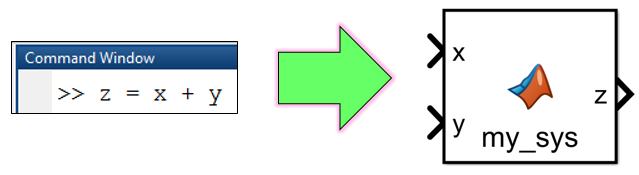

tf_i_should_create_SL_block = true;

if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'SIM_SMD_WILL_BE_DELETED';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)   
                          
    % Put BOTH equations into one block 
    BLOCK_NAME = [MODEL_NAME,'/THE_HAND_DYN_SYS'];
    matlabFunctionBlock( BLOCK_NAME, ...
                          my_ACC_and_lambda_col(1), my_ACC_and_lambda_col(2), my_ACC_and_lambda_col(3), ...
                          my_ACC_and_lambda_col(4), my_ACC_and_lambda_col(5), ...
                         'Optimize', false, ...
                         'Outputs', {'theta_DD', 'alpha_DD', 'phi_DD', 'Lambda_1', 'Lambda_2'}   );  
                     
                            % make the block YELLOW                   
   set_param( BLOCK_NAME,'BackgroundColor', '[0.996078, 1.000000, 0.705882]');  
   
   % create another block of A and b
    BLOCK_NAME = [MODEL_NAME,'/THE_A_b_HAND_DYN_SYS'];
    matlabFunctionBlock( BLOCK_NAME, ...
                          A, ...
                          b, ...
                         'Optimize', false, ...
                         'Outputs', {'A', 'b'}   );  
                     
                            % make the block YELLOW                   
   set_param( BLOCK_NAME,'BackgroundColor', '[0.996078, 1.000000, 0.705882]');     
   
end

# Next steps - a dynamic model in **Simulink**

Having derived the equations of motion for the 4bar mechanism, the next sensible step is to solve these equations ... and we'll use Simulink to do that.

So NEXT steps will be

- Open the script called `DEMO_03b_bh_4bar_DYN_sim.mlx`

- Run the script and explore the Simulink model `bh_4bar_model_DYN.slx`

- Run the Simulink model `bh_4bar_model_DYN.slx`

We have implemented our hand derivation in the subsystem called` Hand_model_LAG_CONSTRAINTS`

  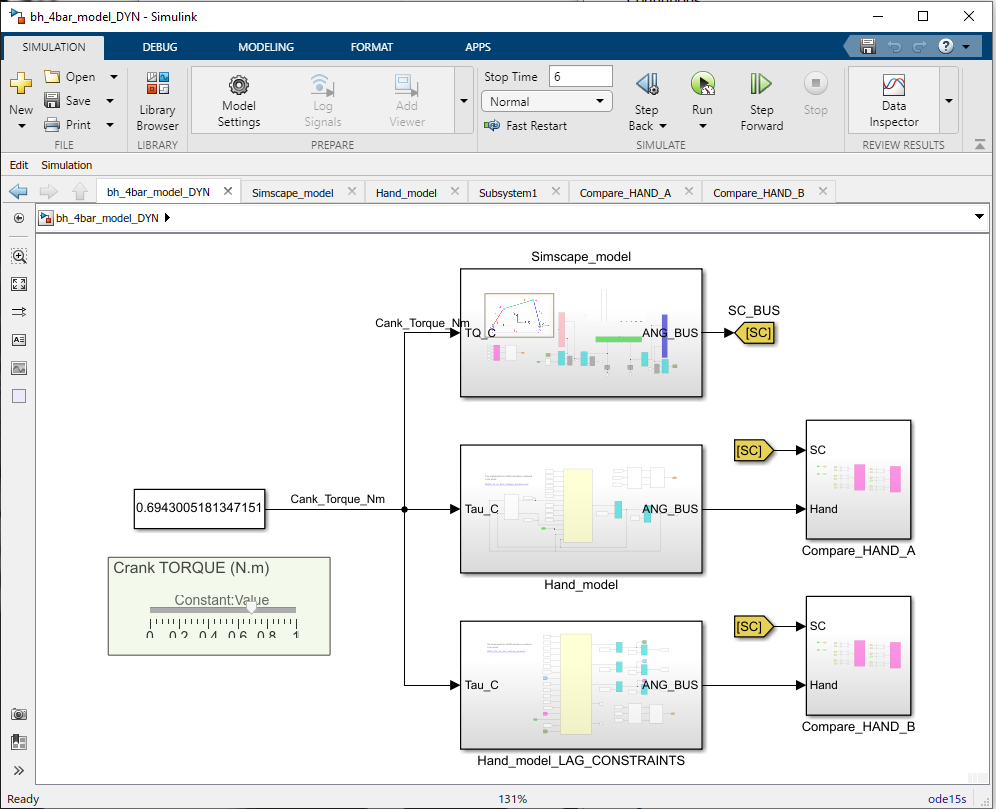

# Local functions only beyond this point

Implement Laranges equation:     $\frac{d}{\textrm{dt}}\frac{\partial L}{\partial \dot{q_k } }\;\;\;-\;\;\frac{\partial L}{\partial q_k }$

Function INPUTS:

- `in_L` - the Lagrangian, a symbolic expression

- `in_PV_HOLD_list` - a 2 element array containing the symbols $\left\lbrack \;q\;,\;\dot{q} \;\;\right\rbrack$

- `in_MAIN_list` - a list of symbolic symbols of the form  $\left\lbrack \;\;\textrm{THETA}\left(t\right),\textrm{diff}\left(\textrm{THETA}\left(t\right),t\right),\;\ldotp \ldotp \ldotp \ldotp \ldotp \;\textrm{etc}\;\right\rbrack$

- `in_HOLD_list` - a list of symbolic symbols of the form  $\left\lbrack \;\;\textrm{theta},\;\textrm{theta}\_\textrm{dot},\;\ldotp \ldotp \ldotp \ldotp \ldotp \;\textrm{etc}\;\right\rbrack$

Function OUTPUTS:

- `the_EOM` -Our symbolic equation of motion for the generalised co-ordinate $q$.  The expression contains the HOLD symbols

function the_EOM = LOC_do_lagrange(in_L, in_PV_HOLD_list, in_MAIN_list, in_HOLD_list)
   
    syms t 
    
   THE_q      = in_PV_HOLD_list(1);
   THE_qdot   = in_PV_HOLD_list(2);
    
   THE_L      = in_L;
   THE_L      = subs(THE_L, in_MAIN_list, in_HOLD_list);
   
   dLdq       = diff(THE_L, THE_q);     % DIFF
   
   dLdqdot    = diff(THE_L, THE_qdot);  % DIFF
   dLdqdot    = subs(dLdqdot, in_HOLD_list, in_MAIN_list);
   
   dt_dLdqdot = diff(dLdqdot, t);       % DIFF
   
   
   the_EOM    = dt_dLdqdot - dLdq;
   
   the_EOM    = subs(the_EOM, in_MAIN_list, in_HOLD_list);
      
end